# Order selection of ARMA model

*We can determine the order P and Q of the model using different evaluation criteria*

**Configurate the path and clear the workspace, etc.**

clc; close all; clear;
addpath(genpath(fullfile('../')));

## Load an IR dataset  and a noise sample

nameIRms = "IR44K_2s_1000ms";

fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
IRms = struct2cell(load(dir+nameIRms));
IRms = IRms{1};
IRms =IRms(:,2);
IRms = [IRms{:}];

noise = randn(fs,1);
noise = noise./max(noise);

## Test for whiteness of the signal

When the input noise is filtered by the ARMA model, the output will show a flatter spectral shape. This is called spectral Whitening.

Using the estimated coefficients we can calculate the spectral flatness of the filtered noise.

nfft = 512;
noverlap = nfft/2;
orderP = 50;
orderQ = 50;
flatness_models = zeros(orderP,orderQ);
win = hann(nfft);
fsmmax = -60;

for p = 1:orderP
    for q = 1:orderQ
        noise_aug = conv(noise, IRms(:,1));
        noise_aug = noise_aug(1:fs);
        noise_aug = noise_aug./max(noise_aug);
        
        [Pxx, ma_params, ar_params] = arma_power_est(noise_aug,p,q,nfft,fs);
   
        % Filter the noise sample with the estimated model
        noise_flat = filter(ar_params,ma_params,noise_aug);
        noise_flat = noise_flat(1:fs);
        flatness = spectralFlatness(noise_flat,fs,'Window',win,'OverlapLength',noverlap, "FFTLength",nfft, 'SpectrumType',"power");
        
        flatness_models(p,q) = mean(flatness);
    end
end
tonality = min(10*log10(flatness_models)./fsmmax,1);

## Visualize flatness and select lowest

Visualization will be done using a Mesh with the average flatness being on the Z axis and the order P and Q on the X and Y axis respectively

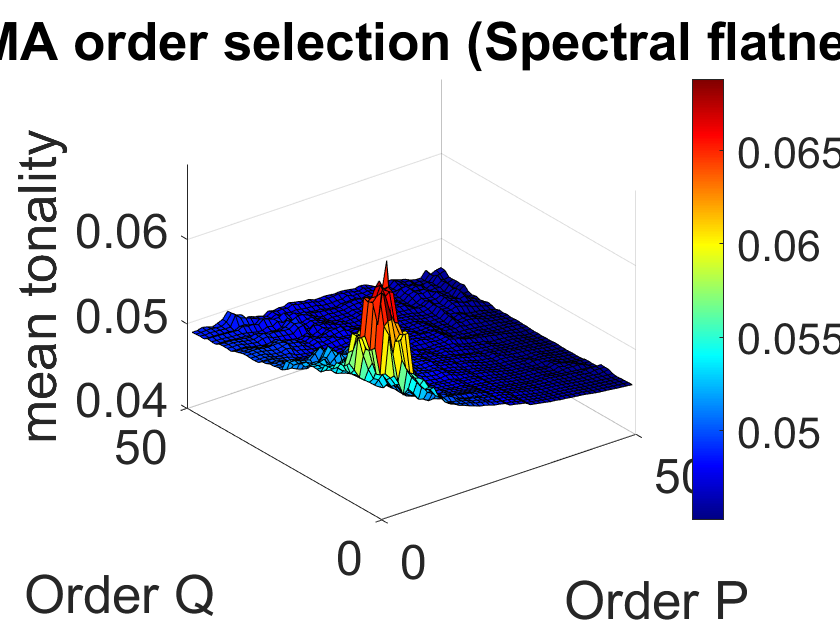

figure
[P,Q] = meshgrid(1:orderP);

surf(P,Q,tonality);
colormap jet
c = colorbar;
ylabel(c,"Tonality");
xlabel("Order P"); ylabel("Order Q"); zlabel("mean tonality");
ax = gca;
ax.FontSize = 24;
title("ARMA order selection (Spectral flatness)","FontSize",36);

The model seems a fine fit for an order (P,Q) = (12,12)